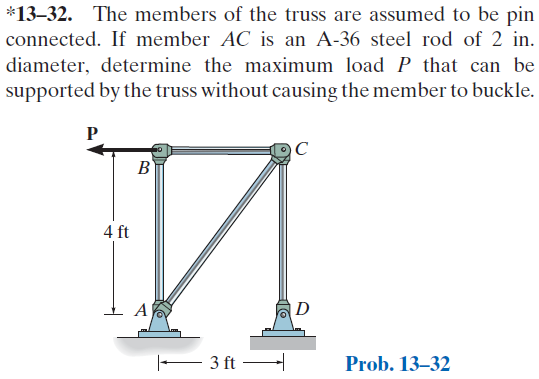

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-32P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-32P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

theta = atand(sym(1.5)/sym(2))*u.deg;
Pvar = sym('P', 'positive');
[Pcr Pmax] = deal(default_struct('buckling', 'yield'));
jointA = [0 0]*u.ft;
jointB = [0 4]*u.ft;
jointC = [3 4]*u.ft;
jointD = [3 0]*u.ft;

# member data

D = 2*u.in;
E = rewrite(29e3*u.ksi, [u.kip u.ft]);
A = rewrite(sympi/4*D^2, u.ft);
I = rewrite(sympi/4*(D/2)^4, u.ft);
L = 5*u.ft;
sigma_yield = 36*u.ksi;
Evar = sym('E');
Avar = sym('A');

# truss

t = Truss;
t = t.add('reaction', 'Ra', {'Rax' 'Ray'}, jointA);
t = t.add('reaction', 'Rd', {'Rdx' 'Rdy'}, jointD);
t = t.add('concentrated', 'Pb', [-Pvar 0], jointB);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('member', 'Fab', jointA, jointB);
t = t.add('member', 'Fbc', jointB, jointC);
t = t.add('member', 'Fcd', jointC, jointD);
t = t.add('member', 'Fac', jointA, jointC, E, A);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');
E = rewrite(E, u.ksi);
A = rewrite(A, u.in);
I = rewrite(I, u.in);
D = rewrite(D, u.in);

# joint displacements

ua

$$ua = \left(\begin{array}{cc} \mathrm{uA} & 0\\ \mathrm{vA} & 0\\ \mathrm{uB} & -\frac{P\,\left(21112\,\pi \,\mathrm{kip}+A\,\text{E}\right)}{2088\,A\,\text{E}\,\pi }\,\frac{\mathrm{ft}}{\mathrm{kip}}\\ \mathrm{vB} & 0\\ \mathrm{uC} & -\frac{P\,\left(14848\,\pi \,\mathrm{kip}+A\,\text{E}\right)}{2088\,A\,\text{E}\,\pi }\,\frac{\mathrm{ft}}{\mathrm{kip}}\\ \mathrm{vC} & \frac{16\,P}{3\,A\,\text{E}}\,\mathrm{ft}\\ \mathrm{uD} & 0\\ \mathrm{vD} & 0 \end{array}\right)$$

# forces on the truss

ma_f_m = ma.f.m %#ok<NASGU> 

$$ma\_f\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fbc} & P\\ \mathrm{Fcd} & \frac{4\,P}{3}\\ \mathrm{Fac} & -\frac{5\,P}{3} \end{array}\right)$$

la_f_c = la.f.c %#ok<NASGU> 

$$la\_f\_c = \left(\begin{array}{cccc} \mathrm{Ra} & P & \frac{4\,P}{3} & 0\\ \mathrm{Rd} & 0 & -\frac{4\,P}{3} & 0\\ \mathrm{Pb} & -P & 0 & 0 \end{array}\right)$$

ma_f_c = ma.f.c %#ok<NASGU> 

$$ma\_f\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fbc} & P & 0 & 0\\ \mathrm{Fcd} & 0 & -\frac{4\,P}{3} & 0\\ \mathrm{Fac} & -P & -\frac{4\,P}{3} & 0 \end{array}\right)$$

la_f_m = la.f.m %#ok<NASGU> 

$$la\_f\_m = \left(\begin{array}{cc} \mathrm{Ra} & \frac{5\,P}{3}\\ \mathrm{Rd} & \frac{4\,P}{3}\\ \mathrm{Pb} & P \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fbc} & 4\,P\,\mathrm{ft}\\ \mathrm{Fcd} & 4\,P\,\mathrm{ft}\\ \mathrm{Fac} & 0 \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 0 & 0\\ \mathrm{Rd} & 0 & 0 & -4\,P\,\mathrm{ft}\\ \mathrm{Pb} & 0 & 0 & 4\,P\,\mathrm{ft} \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & -4\,P\,\mathrm{ft}\\ \mathrm{Fcd} & 0 & 0 & -4\,P\,\mathrm{ft}\\ \mathrm{Fac} & 0 & 0 & 0 \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Ra} & 0\\ \mathrm{Rd} & 4\,P\,\mathrm{ft}\\ \mathrm{Pb} & 4\,P\,\mathrm{ft} \end{array}\right)$$

# maximum load due to buckling

Pcr.buckling = rewrite(sympi^2*E*I/L^2, u.kip);
Pcr_buckling = vpa(Pcr.buckling, 4) %#ok<NASGU> 

$$Pcr\_buckling = 62.44\,\mathrm{kip}$$

Pmax.buckling = solve(abs(ms.f.m.Fac) == Pcr.buckling);
Pmax_buckling = vpa(Pmax.buckling, 4) %#ok<NASGU> 

$$Pmax\_buckling = 37.47\,\mathrm{kip}$$

# maximum load due to yield

Pcr.yield = rewrite(solve(sigma_yield == Pvar/A), u.kip);
Pcr_yield = vpa(Pcr.yield, 5) %#ok<NASGU> 

$$Pcr\_yield = 113.1\,\mathrm{kip}$$

Pmax.yield = solve(abs(ms.f.m.Fac) == Pcr.yield);
Pmax_yield = vpa(Pmax.yield, 4) %#ok<NASGU> 

$$Pmax\_yield = 67.86\,\mathrm{kip}$$

# clean up

new_assum = old_assum;
clear ma_f_m la_f_c ma_f_c la_f_m;
clear ma_m_m la_m_c ma_m_c la_m_m;
clear Pcr_buckling Pmax_buckling;
clear Pcr_yield Pmax_yield;